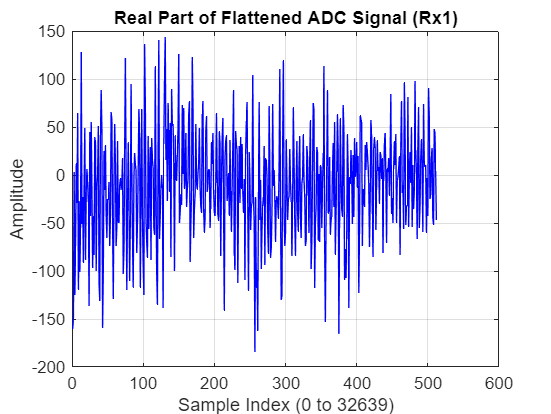

% Load the data
data = load('000002.mat');  % Replace with your actual file name
adc = data.adcData;

% Extract Rx1 data [128 x 255]
rx = 1;
rx_data = squeeze(adc(:, rx, :, 1));  % [128 x 255]

% Flatten into a 1D vector (column-wise → time sequence)
flattened_signal = reshape(rx_data, [], 1);  % [128*255 x 1]

% Plot real part
figure;
plot(real(flattened_signal), 'b');
title('Real Part of Flattened ADC Signal (Rx1)');
xlabel('Sample Index (0 to 32639)');
ylabel('Amplitude');
grid on;

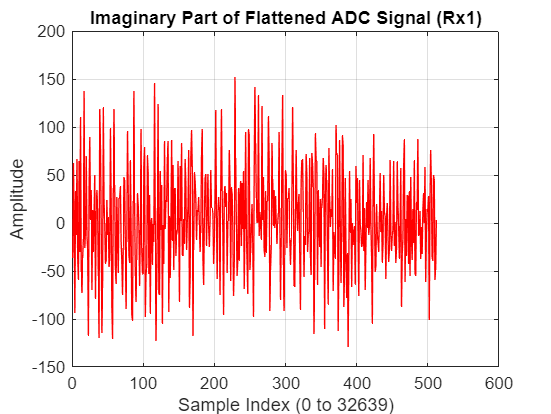


% Plot imaginary part
figure;
plot(imag(flattened_signal), 'r');
title('Imaginary Part of Flattened ADC Signal (Rx1)');
xlabel('Sample Index (0 to 32639)');
ylabel('Amplitude');
grid on;